p=zeros(1,20);

p(1)=pi;%初值

for i=1:19
    p(i+1)=pi+0.5*sin(p(i)/2);
end
p

p =     3.1416    3.6416    3.6260    3.6270    3.6269    3.6269    3.6269    3.6269    3.6269    3.6269    3.6269    3.6269    3.6269    3.6269    3.6269    3.6269    3.6269    3.6269    3.6269    3.6269


q=1:20

q =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20


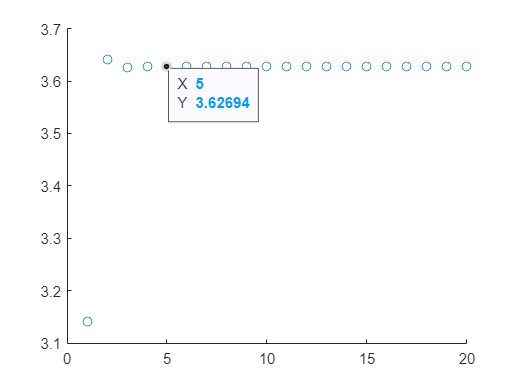

scatter(q,p)

k=1/4;%g'(x)<=1/4;
Error=zeros(1,20);

for n=1:20
    Error(1,n)=k^n/(1-k)*abs(p(2)-p(1));
end

error=Error(Error<=1E-2)

error =     0.0026    0.0007    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
